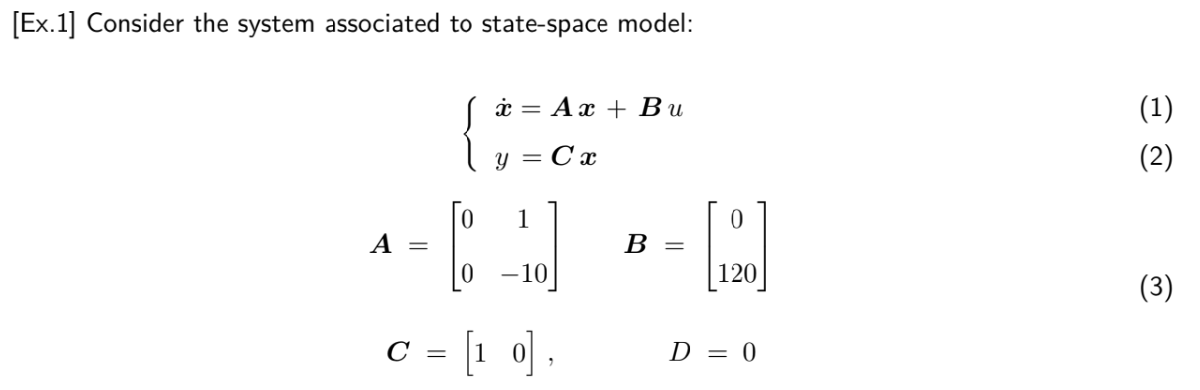

%%Implementazione sistema

clear all;
close all;
clc;

A = [0 1; 0 -10];
B = [0; 120];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);  % associa le matrici A,B,C,D alle variabili dello state space model
G = tf(sys)  % tf del processo


G =
 
     120
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


G_bode = zpk(G)  %% Forma fattorizzata di Bode del processo


G_bode =
 
    120
  --------
  s (s+10)
 
Continuous-time zero/pole/gain model.
Model Properties



poles = pole(sys);  % Restituisce un vettore con la posizione dei poli in s
n_poles_zero = sum(abs(poles) < 1e-6); %Calcola il numero di poli nell'origine (La toll. è necessaria a causa dei calcoli appr. di Matlab)

%%Controllore

required_integrators = 2; %Tracking rampa senza errore
controller_integrators = required_integrators - n_poles_zero; %Poli richiesti al controllore

BODE METHOD:

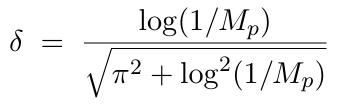

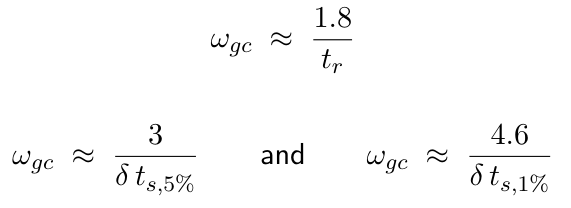

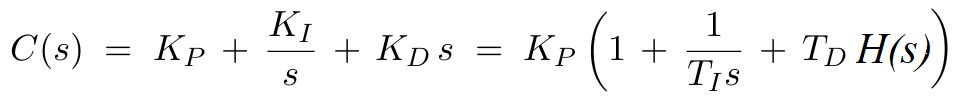

wgc is the angular frequency at which the magnitude of the open-loop chain L(jw)=C(jw)*G(jw) is equal to 1 (0 in dB)

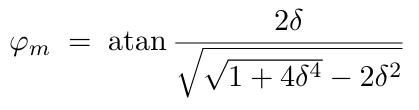

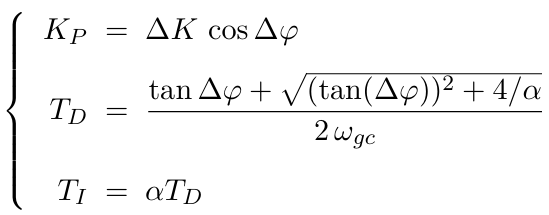

tr = 0.15; %t rise in secondi

Mp = 0.2; %Sovraelongazione

omega_gc = 1.8/tr;

T_L = 1/(10 * omega_gc);


% Calcola G(j*omega_gc)
G_jomega_gc = polyval(G.num{1}, 1j*omega_gc) / polyval(G.den{1}, 1j*omega_gc);
%polyval valuta un polinomio, passato come primo termine come array dei
%propri coefficienti in ordine decrescente di grado in una serie di
%pulsazioni angolari specificata nel secondo termine come array

Delta_K = inv(abs(G_jomega_gc));

delta = (log(1/Mp))/(sqrt(pi^2+(log(1/Mp))^2));

phi_m = atan((2*delta)/(sqrt(sqrt(1+4*delta^4)-2*delta^2))); %Margine di fase desiderato

Delta_phi = -pi + phi_m - angle(G_jomega_gc); %Quanta fase manca al processo per raggiungere il margine di fase desiderato

K_P = Delta_K*cos(Delta_phi);

alpha = 20000;

T_D = (tan(Delta_phi)+sqrt((tan(Delta_phi))^2+(4/alpha)))/(2*omega_gc);
T_I = alpha * T_D;

s = tf('s');

H = s/(1+T_L*s); %Derivativo reale

C = K_P*(1+(1/(T_I*s))+T_D*H)


C =
 
  7.792 s^2 + 378.6 s + 1.546
  ---------------------------
       2.041 s^2 + 245 s
 
Continuous-time transfer function.
Model Properties



C_bode = zpk(C)


C_bode =
 
  3.8171 (s+48.59) (s+0.004083)
  -----------------------------
            s (s+120)
 
Continuous-time zero/pole/gain model.
Model Properties



L = C * G;

T = feedback(L, 1);

info_step = stepinfo(T)

info_step = struct with fields:
         RiseTime: 0.1075
    TransientTime: 0.5933
     SettlingTime: 0.5933
      SettlingMin: 0.9324
      SettlingMax: 1.2100
        Overshoot: 20.9988
       Undershoot: 0
             Peak: 1.2100
         PeakTime: 0.2433
